clear all; close all;
load('Entire_region_Summer.mat')

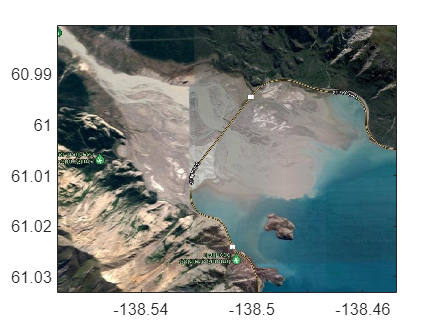

img=imread('Yukon_delta.jpg'); 
image([ -138.447718 -138.570218],[61.033109 60.980258], img);
hold('on');

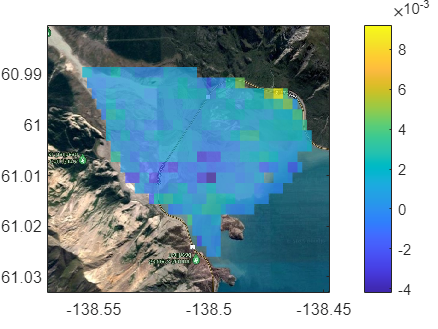

[nr,nc]=size(Z_slopes);
s= pcolor([X(:,1);nan],[Y(1,:), nan],[Z_slopes nan(nr,1); nan(1,nc+1)]' );
s.EdgeColor = 'none' ;
s.FaceAlpha = 0.7;
colorbar

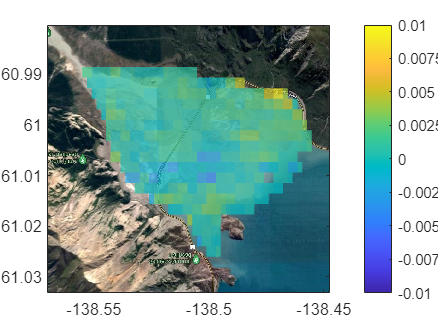

c =   ColorBar (Annual-Maximum EVI per year) with properties:

    Location: 'eastoutside'
      Limits: [-0.0100 0.0100]
    FontSize: 9
    Position: [0.8284 0.1109 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


caxis([-0.01, 0.01]);

c = colorbar('XTickLabel',{-0.01, -0.0075, -0.005, -0.0025, 0, 0.0025, 0.005, 0.0075, 0.01}, ...
    'XTick', -0.01:0.0025:0.01); 
c.Label.String = 'Annual-Maximum EVI per year';
c.Label.FontName = 'Dialog'

%c.Ticks = linspace(0, 1, 9);

%c.TickLabels ={-0.01, -0.0075, -0.005, -0.0025, 0, 0.0025, 0.005, 0.0075, 0.01};
c.FontSize = 10

c =   ColorBar (Annual-Maximum EVI per year) with properties:

    Location: 'eastoutside'
      Limits: [-0.0100 0.0100]
    FontSize: 10
    Position: [0.8284 0.1109 0.0381 0.8152]
       Units: 'normalized'

  Show all properties


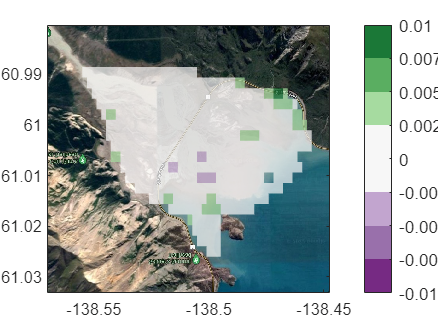

RGB=[118,42,131
    153,112,171
    194,165,207
    247,247,247
    247,247,247
    166,219,160
    90,174,97
    27,120,55];
colormap(RGB./255)

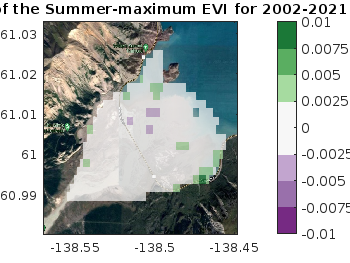


%xlabel("Longitude", 'FontName','SansSerif'); 
%ylabel("Latitude", 'FontName','SansSerif'); 
title("Slopes of the Summer-maximum EVI for 2002-2021", 'FontName', "Dialog")

set(gca, 'xDir', 'reverse') 
set(gca,'XAxisLocation','top','YAxisLocation','right','ydir','reverse');
camroll(180)

hold off;
saveas(gcf,'Published_plots\Figure_14.pdf')

clear s; clear c; clear img;
